clear all

### Constants

global m g h kp hn0 hp0 kn Eg Ep En Pi
m1 = 0.8; %                   [kg]      unloaded mass
m0 = m1 + 2; %              [Kg]      loaded mass
g = 9.81; %                   [m/s^2]   gravity acceleration

Des_Long = -10E-3;%          [m]       desired initial elongation of the positive spring
kpinit = round(-m0*g/Des_Long)%        [N/m]     stiffness of the main spring

kpinit = 2747

stroke = 0.2; %               [m]       desired stroke in each direction 
h = [Des_Long-stroke:0.001:Des_Long+stroke]; %range of heights 

## Variables

hn0 = -0.1;%initial position negative spring
%Default hn0 = -0.1
hp0 = 0.01;%initial position positive spring
%Default hp0 = 0
m = 350 ;%mass that is on the system
m = m0

m = 2.8000

%Default m = 350
r = 0.91 ;% ration between kn kp
kp = 31800%variable stiffness

kp = 31800

kprel = (kp -kpinit)/kpinit * 100

kprel = 1.0576e+03

kp  = kpinit

kp = 2747

kn = - r*kp; %relation between the positive and negative stiffness
computeEnergy(); %computing the energy equations
r_real = -kn/kp

r_real = 0.9100

[C, I] = min(Pi);
equilibriumpos = h(I)

equilibriumpos = 0.1900

### Force balance

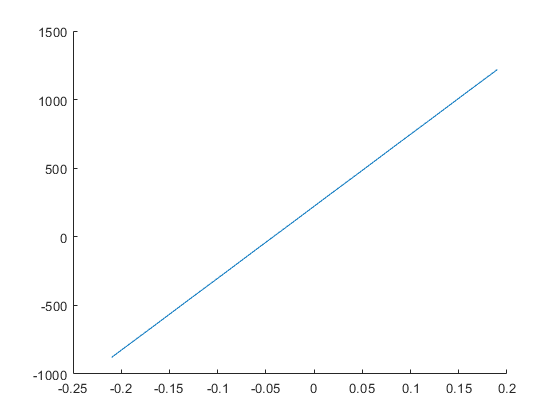

Fn = kn * (h-hn0);
Fp = kp * (h-hp0);
Fres = Fp- Fn;
figure()
hold on
plot(h,Fres)

## Resulting Energy Curves

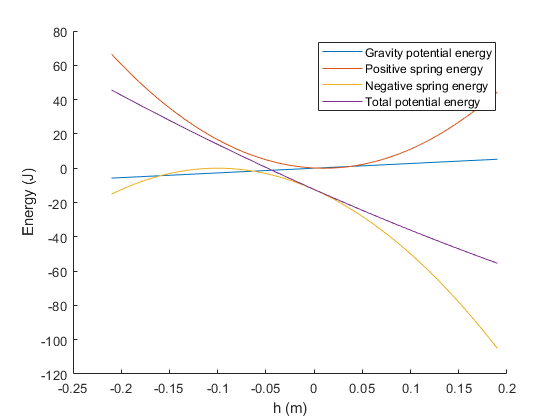

figure()
clf;
hold on
plot(h,Eg)
plot(h,Ep)
plot(h,En)
plot(h,Pi)
legend('Gravity potential energy','Positive spring energy','Negative spring energy',"Total potential energy")
xlabel('h (m)')
ylabel('Energy (J)')

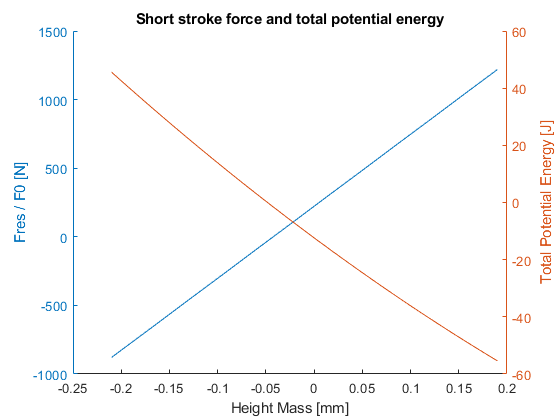

x_axis = h; %choice of x_axis 

fig = figure();
hold on
title('Short stroke force and total potential energy')

yyaxis left
plot(x_axis,Fres) 
ylabel('Fres / F0 [N]') 
%ylim([-0.5 0.5]) %limits the plot shape

yyaxis right
plot(x_axis, Pi)
ylabel('Total Potential Energy [J]') 

xlabel('Height Mass [mm]')

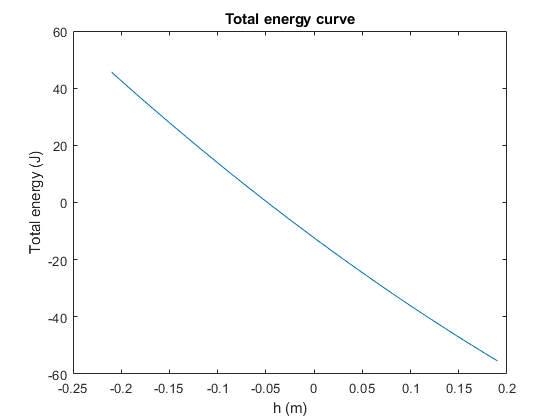

%xlim([-obj.r2*pi*1.5 0])
            
figure()
clf;
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title('Total energy curve')


%figure()
%clf;

%plot(h(1:length(h)-1),dPi)
%title('dPi')

## Resulting potential energy curves vs relation kp-kn

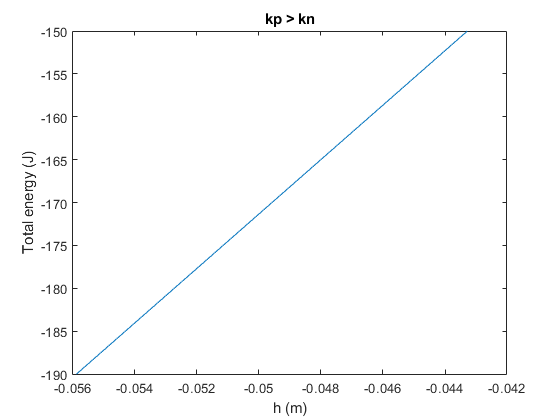

hn0 = -0.1;
hp0 = 0;
m = 350;

lims = [-190;-150];

figure() % case kp > kn
kn = - 0.9*kp;
computeEnergy(); %computing the energy equations
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title("kp > kn")
ylim(lims)

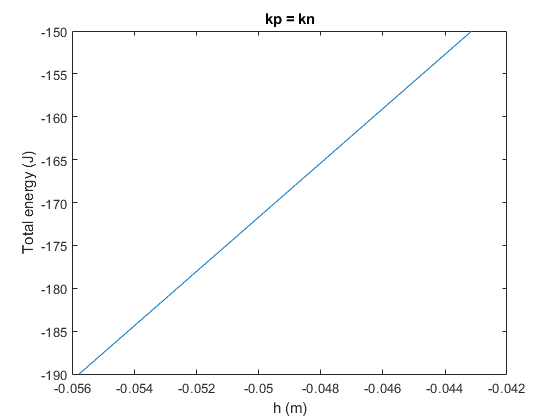


figure() % case kp = kn
kn = -kp;
computeEnergy(); %computing the energy equations
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title("kp = kn")
ylim(lims)

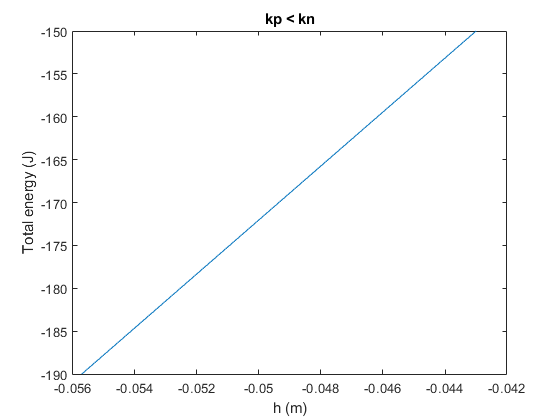


figure() % case kp < kn
kn = - 1.1*kp;
computeEnergy(); %computing the energy equations
plot(h,Pi)
xlabel('h (m)')
ylabel('Total energy (J)')
title("kp < kn")
ylim(lims)

## Height variation versus equilibrium position

Des_Long = -100E-3;%          [m]       desired initial elongation of the positive spring
kpinit = round(-m0*g/Des_Long)%        [N/m]     stiffness of the main spring

kpinit = 275

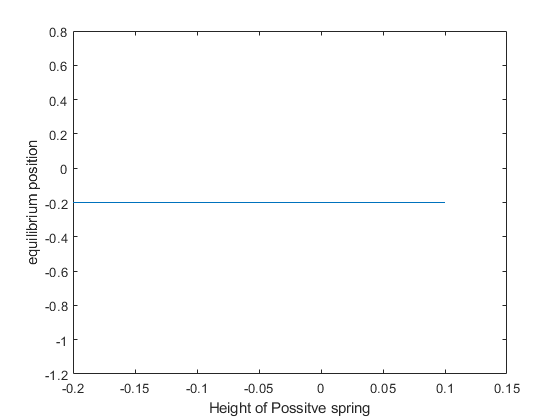

stroke = .1; %               [m]       desired stroke in each direction 
h = [Des_Long-stroke:0.001:Des_Long+stroke]; %range of heights

hn0 = -0.1;%initial position negative spring
hp0 = 0;

heights = [-0.2:0.001:0.1]; %various heights of the positive springs

%Default hp0 = 0
m = 350;
%Default m = 350
r = 0.9; %ration between kn and kp
kp = kpinit;
kn = - r*kpinit; %relation between the positive and negative stiffness

equilibriums = zeros(1,length(heights));

for i = 1:length(heights)
    hp0 = heights(i);
    computeEnergy(); %computing the energy equations
    [C, I] = min(Pi);
    equilibriums(i) = h(I);
end

figure()
clf;
plot(heights,equilibriums)
xlabel('Height of Possitve spring')
ylabel('equilibrium position')


L = length(equilibriums);
a = (equilibriums(L) - equilibriums(1))/(heights(L)-heights(1)) %slope of the line

a = 0

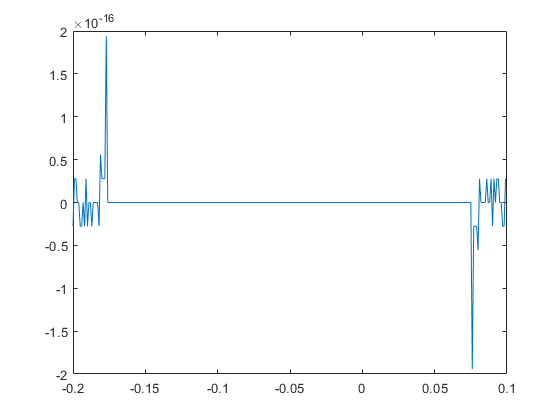

plot(heights(1:L-1),diff(smooth(equilibriums,50)))

## Stiffness variation versus equilibrium position

Des_Long = -100E-3;%          [m]       desired initial elongation of the positive spring
kpinit = round(-m0*g/Des_Long)%        [N/m]     stiffness of the main spring

kpinit = 275

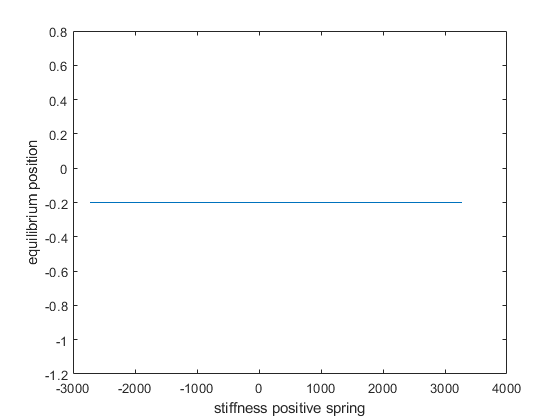


hn0 = -0.1;%initial position negative spring
hp0 = 0;
stifvar = 3000;
stiffness = [kpinit-stifvar:1:kpinit+stifvar];
L = length(stiffness);
equilibriums = zeros(1,L );


stroke = .1; %               [m]       desired stroke in each direction 
h = [Des_Long-stroke:0.001:Des_Long+stroke]; %range of heights

for i = 1:L
    kp = stiffness(i);
    computeEnergy(); %computing the energy equations
    [C, I] = min(Pi);
    equilibriums(i) = h(I);
end
figure()
clf;
plot(stiffness,equilibriums)
xlabel('stiffness positive spring')
ylabel('equilibrium position')

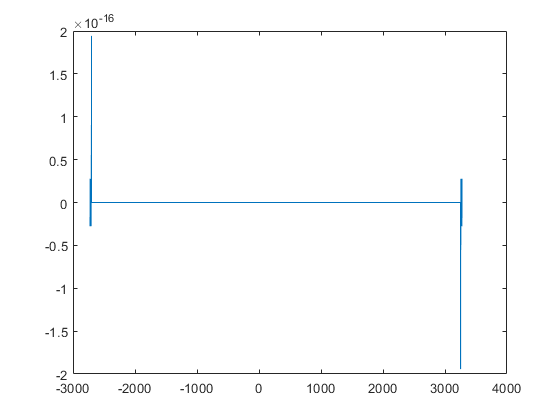

plot(stiffness(1:L-1),diff(smooth(equilibriums,50)))

## Stiffness & initial stiffness variation versus equilibrium position

Des_Long = -[10:10:200]*1E-3;%          [m]       desired initial elongation of the positive spring
var_kpinit = -m0*g./Des_Long%        [N/m]     stiffness of the main spring

var_kpinit = 	1.0e+03 *

    2.7468    1.3734    0.9156    0.6867    0.5494    0.4578    0.3924    0.3433    0.3052    0.2747    0.2497    0.2289    0.2113    0.1962    0.1831    0.1717    0.1616    0.1526    0.1446    0.1373



hn0 = -0.1;%initial position negative spring
hp0 = 0;
stifvar = 5000;

H = length(var_kpinit);
B = length([-stifvar:10:stifvar]);
equilibriums = zeros(H,B);
stiffness = zeros(H,B);
init =  zeros(H,B);

stroke = .1; %               [m]       desired stroke in each direction
for j = 1:length(var_kpinit)
    kpinit = var_kpinit(j);
    stiffness(j,:) = [kpinit-stifvar:10:kpinit+stifvar];
    L = length(stiffness);
     
    h = [Des_Long-stroke:0.0001:Des_Long+stroke]; %range of heights
    for i = 1:L
        kp = stiffness(j,i);
        computeEnergy(); %computing the energy equations
        [C, I] = min(Pi);
        equilibriums(j,i) = h(I);
        init(j,i) = kpinit;
    end
end


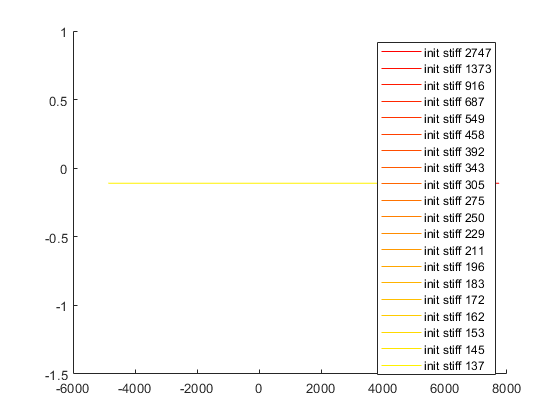

figure()
clf
hold on
legendstring = []; %keeping track of legend str;
% use colormap parula because it goes blue -> yellow:
cmap = autumn();
% define the color limits:
l1 = -10;
l2 = 2;
clim = [l1, l2];
% define the values to use for line colors:
step = (l2 - l1)/H;
vals = [l1:step:l2];
% indices into cmap of vals, using clim as the upper and lower limits:
idx = 1+round((vals-clim(1))/(clim(2)-clim(1))*(size(cmap,1)-1));
% colors from colormap at those indices:
line_colors = cmap(idx,:);

for i = 1 : H
    plot(stiffness(i,:),equilibriums(i,:),"Color",line_colors(i,:))
    legendstring = [legendstring; "init stiff " + int2str(round(var_kpinit(i)))];
end
legend(legendstring)

Functions

function computeEnergy()
    global m g h kp hn0 hp0 kn Eg Ep En Pi
    Eg = m*g*h;
    Ep = 0.5*kp*(h-hp0).^2;
    En = 0.5*kn*(h-hn0).^2;
    Pi = Ep + En + Eg;
end